# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Isaac Marval, Diego Pena**

**Fecha: 21-11-2025**

# Tema 4. Ejercicio 1.1. Identificación de círculos

1) Lee la imagen

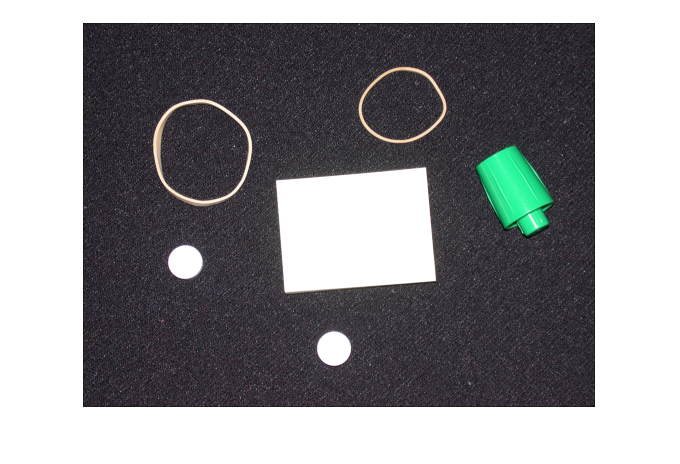

RGB = imread('pillsetc.png');
imshow(RGB);

2) Umbraliza la imagen

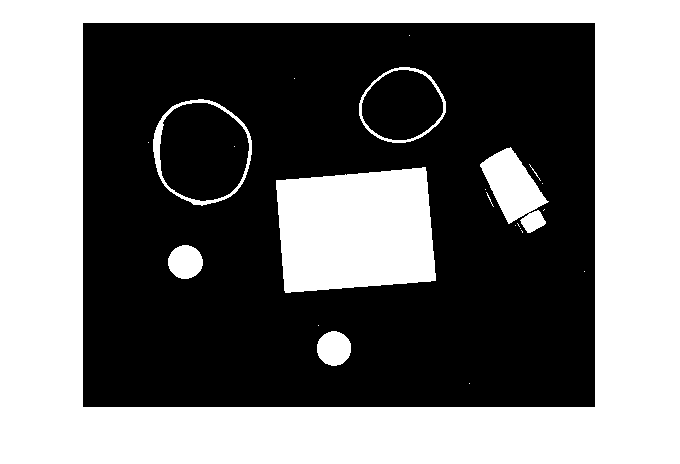

I = rgb2gray(RGB);
bw = imbinarize(I);
imshow(bw)

3) Elimina el ruido

Usando operaciones morfológicas se eliminan los píxeles que no pertenecen a los objetos de interés.

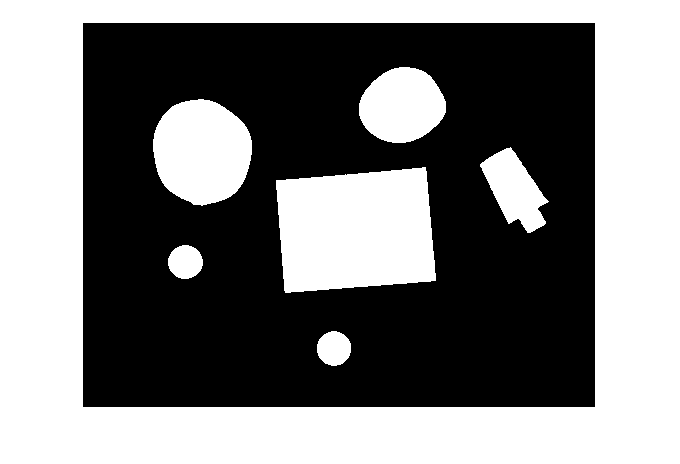

% remove all object containing fewer than 30 pixels
bw = bwareaopen(bw,30);

% fill a gap in the pen's cap
se = strel('disk',2);
bw = imclose(bw,se);

% fill any holes, so that regionprops can be used to estimate
% the area enclosed by each of the boundaries
bw = imfill(bw,'holes');

imshow(bw)

4) Encuentra los contornos

Nos centramos sólo en los límites exteriores. La opción `'noholes' `acelerará el proceso al evitar que la función `bwboundaries` busque contornos internos. 

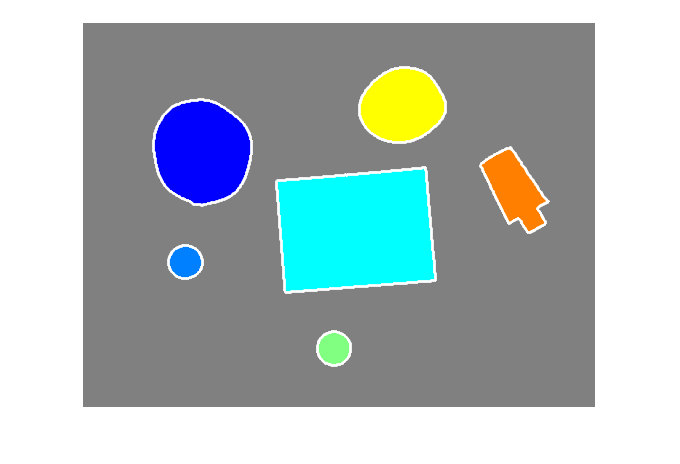

[B,L,n,A] = bwboundaries(bw,'noholes'); % Returns B, a cell array of boundary pixel locations, and matrix L where objects and holes are labeled..

% Display the label matrix 
imshow(label2rgb(L, @jet, [.5 .5 .5]))

hold on  % to draw the next in the same figure

% draws the boundaries of each object.
for k = 1:n
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

Se pide:

- Utilice la ayuda de Matlab para conseguir información sobre la función `regionprops `(parámetros requeridos, propiedades que calcula, etc.).

- Usando dicha función, calcule el área, el perímetro y la circularidad de cada objeto de la imagen previa. 

- Umbralizando el valor de la circularidad, resalte los objetos que sean aproximadamente circulares (p.ej., pintando las boundaries de color diferente). Puede utilizar un slidebar para verificar la influencia del valor del umbral en el conjunto de objetos resaltados. 

# Tema 4. Ejercicio 1.2. Identificación de objetos cóncavos/convexos

- Cargue la imagen `'Figure1.jpg'` 

- Utilice la función `regionprops` para calcular el área, el área convexa y el índice de convexidad (Solidity). Visualice una tabla con las tres propiedades para todos los objetos de la imagen.

- Resalte el borde del objeto convexo ('ConvexHull') de cada objeto: en blanco para los objetos cóncavos y en magenta para los convexos. 

- Utilice un slider para umbralizar el índice de convexidad dentro de los márgenes de los objetos de la imagen (según aparecen en la tabla del punto 2) y compruebe qué objetos son seleccionados al variar el valor del umbral. Justifique si es correcto según los valores obtenidos. 

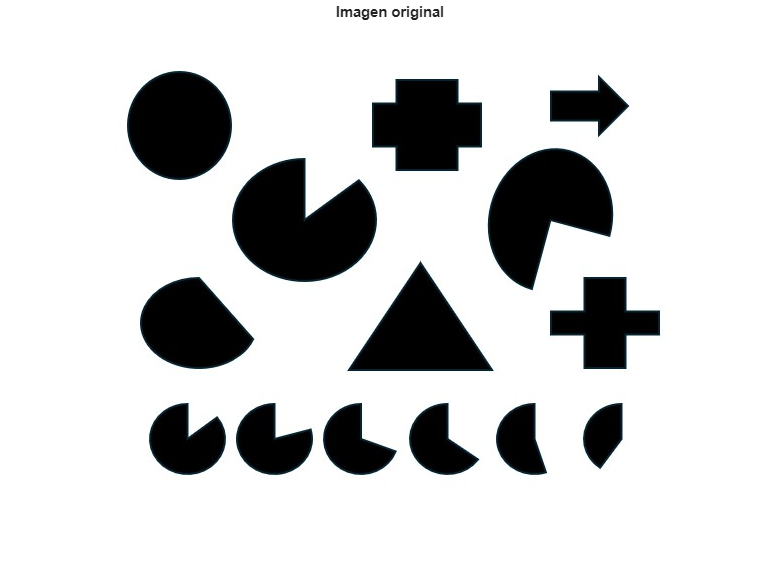


% EJERCICIO 1.2 - OBJETOS CONVEXOS / CÓNCAVOS

I = imread('Figure1.jpg');    % Cargar imagen
figure;
imshow(I);
title('Imagen original');

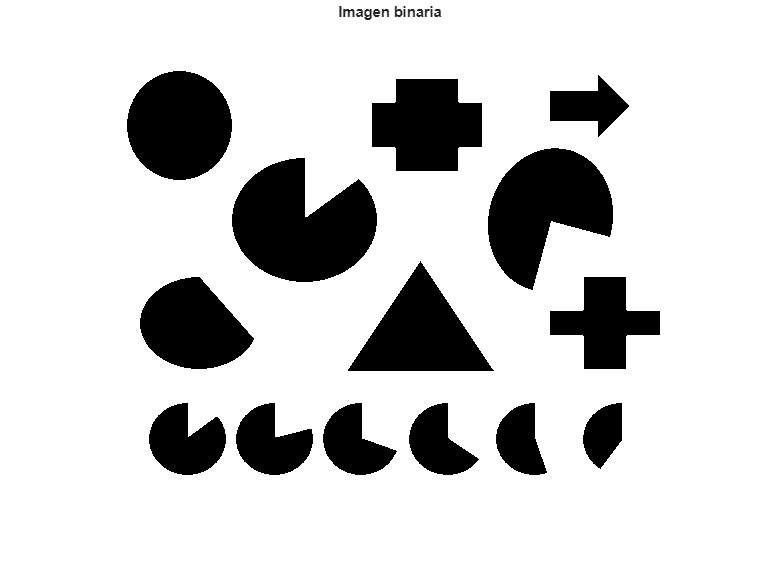



% Binarizar y rellenar agujeros
Igray = rgb2gray(I);
bw = imbinarize(Igray);


imshow(bw);
title('Imagen binaria');

% 2) CALCULO DE AREA, AREA CONVEXA Y SOLIDITY ---------------

bw = ~bw;   % INVERTIR la imagen binaria


L = bwlabel(bw);

stats = regionprops(L, 'Area', 'ConvexArea', 'Solidity', 'ConvexHull');

areas       = [stats.Area]';
areasConv   = [stats.ConvexArea]';
solidity    = [stats.Solidity]';

etiquetas = (1:numel(stats))';
tabla2 = table(etiquetas, areas, areasConv, solidity, ...
    'VariableNames', {'Etiqueta','Area','AreaConvexa','Solidity'});

disp(tabla2);

    Etiqueta    Area     AreaConvexa    Solidity
    ________    _____    ___________    ________

        1        8965        9045       0.99116 
        2        7176        7246       0.99034 
        3        3752        4289        0.8748 
        4       12243       13940       0.87826 
        5        3485        4154       0.83895 
        6        3031        3664       0.82724 
        7        8031        8121       0.98892 
        8        7820        8920       0.87668 
        9        2862        3428       0.83489 
       10       10655       12887        0.8268 
       11        2428        2666       0.91073 
       12        2432        3184       0.76382 
       13        5500        7740       0.71059 
       14        1794        1829       0.98086 




% 3) DIBUJAR CONVEXHULL SEGÚN SOLIDITY ----------------------



umbralSol=0.4

umbralSol = 0.4000

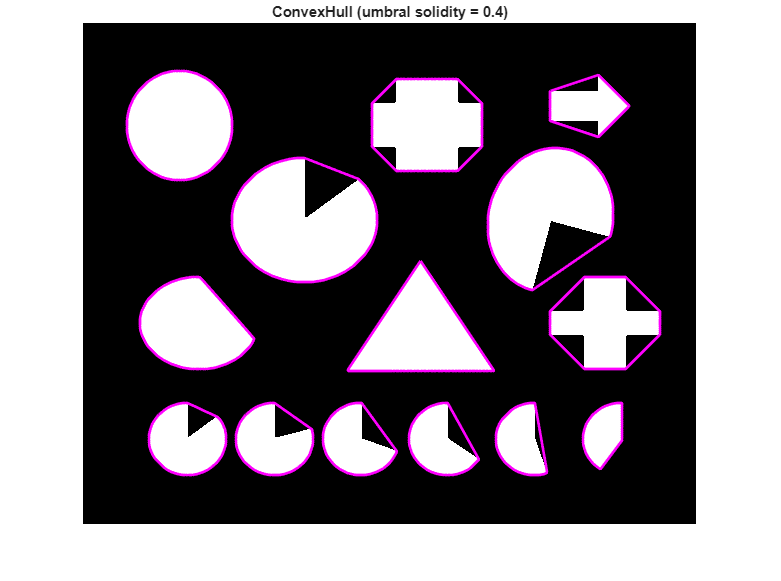


figure;
imshow(bw);
title(['ConvexHull (umbral solidity = ', num2str(umbralSol), ')']);
hold on;

for k = 1:numel(stats)
    hull = stats(k).ConvexHull;  % coordenadas [x,y] del hull
    
    if solidity(k) >= umbralSol
        col = 'm';  % magenta: convexo
    else
        col = 'w';  % blanco: cóncavo
    end
    
    plot(hull(:,1), hull(:,2), col, 'LineWidth', 2);
end

hold off;